load classdata.mat

%Creates a cell array with the names of the people
Names = cell(1,66);
for i = 1:66
    Names(1,i) = y.name(1,2*i);    
end

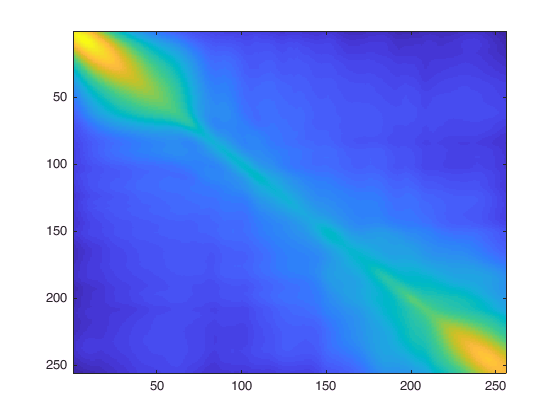

AverageClassFaces = zeros(256,256,66);
for i = 1:66
    AverageClassFaces(:,:,i) = (grayfaces(:,:,2*i)+grayfaces(:,:,2*i-1))/2 ;
end

TotalAverageFace = zeros(256,256);
for i = 1:132
    TotalAverageFace = TotalAverageFace + grayfaces(:,:,i);
end
TotalAverageFace = TotalAverageFace./132;

Sb = zeros(256,256);
for i = 1:66
    Sb = Sb + (2*(AverageClassFaces(:,:,i)-TotalAverageFace)*(AverageClassFaces(:,:,i)-TotalAverageFace).') ;
end
imagesc(Sb)

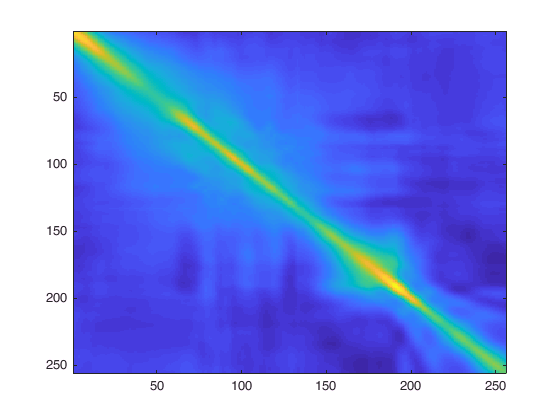


Sw = zeros(256,256);
for i = 1:66
    InsideWithin2 = zeros(256,256);
   for k = 1:2
       InsideWithin1 = (grayfaces(:,:,2*i-2+k) - AverageClassFaces(:,:,i)) * (grayfaces(:,:,2*i-2+k) - AverageClassFaces(:,:,i)).' ;
       InsideWithin2 = InsideWithin2 + InsideWithin1;
   end
    Sw = Sw + InsideWithin2;
end
imagesc(Sw)

% Create Weights and Eigenfaces for Fisherface analysis
faces = grayfaces;
names = Names;
limit = 132;
sFaces = stackim(faces);  % faces stacked in column vectors
nFaces = (sFaces - mean(sFaces,1))./sqrt(length(sFaces(:,1)));  % normalize faces
fCovarriance = nFaces'*nFaces;  % covarriance matrix of faces
[V,D] = eig(fCovarriance);
AllEigenFaces = sFaces*fliplr(V);  % flip Eigenfaces so strongest is first
EigenFaces = AllEigenFaces(:,1:limit);  % limit eigenfaces (and weights indirectly)
allWeights = linsolve(EigenFaces,nFaces);  % generate weights for training set
% allWeights = EigenFaces\nFaces;
limitedWeights = allWeights(end-limit+1:end,:);

% Sb of faces in Eigenspace
AverageClassFaces = zeros(132,66);
for i = 1:66  % create average face for each class (person)
    AverageClassFaces(:,i) = (allWeights(:,2*i)+allWeights(:,2*i-1))/2 ;
end

TotalAverageFace = zeros(132,1);
for i = 1:132  % create average face of all faces
    TotalAverageFace = TotalAverageFace + allWeights(:,i);
end
TotalAverageFace = TotalAverageFace./132;

Sb = zeros(132,132);
for i = 1:66
    Sb = Sb + (2*(AverageClassFaces(:,i)-TotalAverageFace)*(AverageClassFaces(:,i)-TotalAverageFace).') ;
end

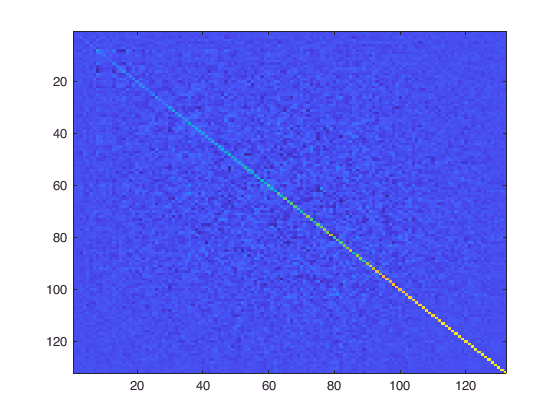

% Sw of faces in Eigenspace
Sw = zeros(132,132);
for i = 1:66
    InsideWithin2 = zeros(132,132);
   for k = 1:2
       InsideWithin1 = (allWeights(:,2*i-2+k) - AverageClassFaces(:,i)) * (allWeights(:,2*i-2+k) - AverageClassFaces(:,i)).' ;
       InsideWithin2 = InsideWithin2 + InsideWithin1;
   end
    Sw = Sw + InsideWithin2;
end
imagesc(Sw)

% Wopt
[Wopt,D] = eig(Sb,Sw);

% Names
[Names,ia,ic] = unique(names);  % get unique names and their indices

% Get new weights of faces with Wopt
newWeights = linsolve(Wopt,allWeights);

% Does this make sense?
% To do a "quick" check, compare the relative distances between
% images of the same class in fisher weights and eigen weights

edist = zeros(132,132);
for i = 1:132
    image1 = allWeights(:,i);
    for j = 1:132
        image2 = allWeights(:,j);
        edist(i,j) = eucDist(image1,image2);
    end
end

fdist = zeros(132,132);
for i = 1:132
    image1 = newWeights(:,i);
    for j = 1:132
        image2 = newWeights(:,j);
        fdist(i,j) = eucDist(image1,image2);
    end
end

eidist = edist(sub2ind(size(edist),1:2:132,2:2:132));
fidist = fdist(sub2ind(size(fdist),1:2:132,2:2:132));
idr = eidist./fidist;  % ratio of differences
mean(idr)

ans = 2.2468

min(idr)

ans = 0.6698

max(idr)

ans = 3.2403

median(idr)

ans = 2.4502

% indices for eodist and fodist
rows = [];
cols = [];
dim = length(fidist(1,:));
for i = 1:2:dim
    rows = [rows [i+2:dim] [i+2:dim]];
    cols = [cols i*ones(1,dim - (i + 1)) (i+1)*ones(1,dim - (i + 1))];
end

eodist = edist(sub2ind(size(edist),rows,cols));
fodist = fdist(sub2ind(size(fdist),rows,cols));

odr = eodist./fodist;
mean(odr)

ans = 2.2505

min(odr)

ans = 0.6466

max(odr)

ans = 3.2973

median(odr)

ans = 2.3307

% actually using fisher faces
model.fisherfaces = EigenFaces*Wopt;
fisherWeights = model.fisherfaces'*reshape(grayfaces,256^2,132,1);
classedWeights = zeros(length(fisherWeights(:,1)),length(Names));
for i = 1:length(Names)
    weightsToAverage = fisherWeights(:,ic == i);  % get all weights under the same class (person)
    classedWeights(:,i) = sum(weightsToAverage,2)./length(weightsToAverage(1,:));  % average weights to single vector
end
% classedWeights = classedWeights(1:limit,:);

model.weights = classedWeights;
model.names = Names;
model.eigenfaces = EigenFaces;

testImage = grayfaces(:,:,34);
figure; colormap gray
imagesc(testImage)
testWeights = model.fisherfaces'*reshape(testImage,256^2,1,1);
distances = sqrt(sum((classedWeights - testWeights).^2, 1));  % compute Euclidean distances

[Distances,NameIndices] = sort(distances)

Distances =    1.0e+10 *

    0.0000    0.0402    0.1258    0.1436    0.1439    0.1947    0.2375    0.2611    0.2630    0.2961    0.2999    0.3127    0.3691    0.4158    0.4732    0.4746    0.4897    0.5118    0.5261    0.5481    0.5914    0.6080    0.6401    0.6909    0.7617    0.7667    0.8058    0.8138    0.8774    0.8840    0.9124    0.9316    0.9396    0.9625    1.0456    1.0626    1.1241    1.1589    1.2029    1.2875    1.4017    1.4354    1.5230    1.5326    1.5390    1.5414    1.5627    1.6075    1.6519    1.8043


NameIndices =      3     4    41    14    13    47    42     6     5    22    52    63    57    21    50    10     9    58    49    20    64    51    19    39    23    40    59    12    24    48    60    25    33    34    26    46    62    11    45    30    17    61    66    29    18    31    65     2     1    37


model.names(NameIndices(1:10))

ans = 1×10 cell array
    'aidencarleyclopton'    'alexbahner'    'marksomerville'    'cusaialfred'    'coreycochran-lepiz'    'nathanestill'    'maxotoadese'    'amyphung'    'alexfrye'    'everardogonzalez'


function D = eucDist(A,B)
    D = sqrt(sum((A - B).^2, 1));
end